% This script was used to get the solved 6th order functions for the joint
% angles over time ( with atleast 1000 data points)
% One at a time, I plugged in the constraint values for each piecewise for
% each joint


clear
syms t time a5 a4 a3 a2 a1 a0
T = 3;
p = t^6 + a5*t^5 + a4*t^4 + a3*t^3 + a2*t^2 + a1*t + a0;
pd = diff(p,t);
pdd = diff(diff(p,t));
% The trajectory will be split up into three 6th-order pieces from
% t=[0, 1), t=[1, 2), and t=[2, 3).
% This script gets the function for each of those pieces for each joint

plot_title="q3 angle_deg @ t=(2, 3)"

tA_time = 2; % Choose the start time of this piece of the trajectory
tA_pos = 291.1; % Choose the start joint angle of this piece of the trajecory
tA_speed = 0;
tA_acc = 0;

tB_time = 3; % Choose the end time of this piece of the trajectory
tB_pos = 308.9; % Choose the end joint angle of this piece of the trajectory
tB_speed = 0;
tB_acc = 0;

p0 = subs(p,t,tA_time) == tA_pos;
p1 = subs(pd,t,tA_time) == tA_speed;
p2 = subs(pdd,t,tA_time) == tA_acc;

p3 = subs(p,t,tB_time) == tB_pos;
p4 = subs(pd,t,tB_time) == tB_speed;
p5 = subs(pdd,t,tB_time) == tB_acc;

S = solve([p0 p1 p2 p3 p4 p5], [a5 a4 a3 a2 a1 a0])

S = struct with fields:
    a5: [1×1 sym]
    a4: [1×1 sym]
    a3: [1×1 sym]
    a2: [1×1 sym]
    a1: [1×1 sym]
    a0: [1×1 sym]


% Once we have these constants, we can add this piece of the function
% to correct the Matlab Function block in the traj_ctrl Simscape model
A0 = S.a0, A1 = S.a1, A2 = S.a2, A3 = S.a3, A4 = S.a4, A5 = S.a5

$$A0 = \frac{1537}{10}$$

$$A1 = 528$$

$$A2 = -780$$

$$A3 = 548$$

$$A4 = -\frac{357}{2}$$

$$A5 = \frac{96}{5}$$

time = tA_time:0.01:tB_time;
P = time.^6 + A5*time.^5 + A4*time.^4 + A3*time.^3 + A2*time.^2 + A1*time + A0

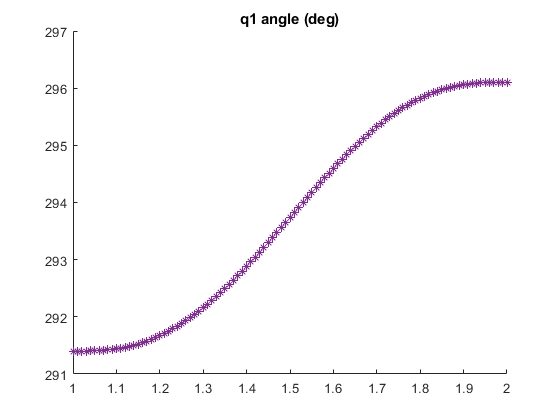

hold on;
plot(time, P, '*', 'Color', '#7E2F8E');
title('q1 angle (deg)')
hold off;